# Banco de peces (Modelo de Agente) - Instrucciones.

**Juan Uriel Legaria Peña**

**Inteligencia Artificial**

**Maestria en Ciencia e Ingenieria de la Computación**

La implementación consta de 3 clases: Fish, FishTank y FishTankRenderer. Como usuarios sin embargo, solo tendremos que lidiar con las últimas 2,  La clase *Fish *guarda variables importantes de los peces, como serian sus vecinos en un momento dado, su dirección, su posición y la dirección media de sus vecinos, también contiene el método update, utilizado en cada paso para tomar la decisión de si el pez debe moverse aleatoriamente o seguir a su grupo de peces cercanos. 

Las clases que nos incumben realmente son:

*FishTank:* Este es el tanque de peces. Al inicializarlo debemos dar como argumento el tamaño que tendrá la pecera, el número de peces que contendrá y el radio de visión dentro del cual se examinaran los vecinos de cada pez. 

*FishTankRenderer*: Esta es la clase que dibujará la pecera a cada paso de la simulación, dando como resultado un arreglo de frames que se pueden usar para generar un video. Como argumento se le da la imagen de un pez (hice una imagen rápida de un pez en inkscape), que se estará dibujando en las diferentes posiciones que ocupen los peces, asi como el tanque de peces a evolucionar. Los frames de la película se obtienen por medio del método renderFishMovie. Dichos cuadros pueden ser posteriorrmente reproducidos usando la función movie(frames) de MATLAB o utilizados para exportar un video (yo elegí este último camino, ya que por alguna razón en mi computadora el video apárece trasladado con el método movie).

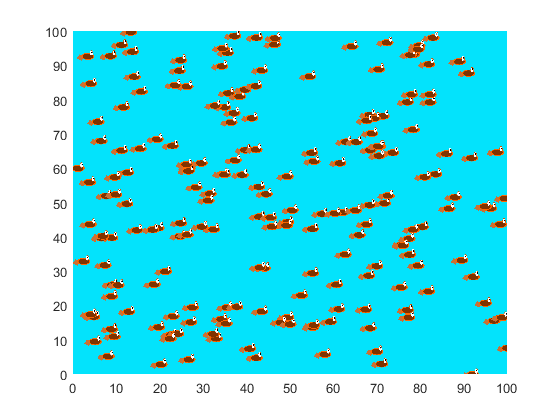

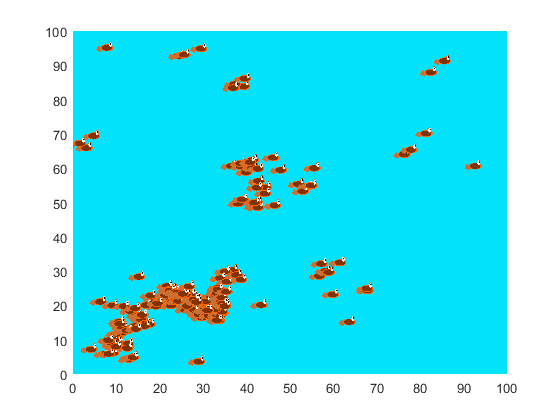

%Establecemos un tamaño para la pecera
width = 100;
height = 100;
%El número de peces
fishNumber = 200;
%El radio de visión
radius = 5;
%Creamos un tanque de peces usando los parámetros anteriores
fishTank = FishTank(width,height,fishNumber,radius);
%Creamos el renderizador para la pelicula del tanque de peces
imgPath = "fish_drawing.png";
renderer = FishTankRenderer(fishTank,imgPath);
%Obtenemos los cuadros de la película
%Como advertencia esto podría tardar varios minutos
%puse una barra que dice el progreso para poder darnos una idea de cuanto
%falta.
%Se puede disminuir el numero de pasos para que no tarde tanto
%pero el video será mas corto
steps = 1000;
m = renderer.renderFishMovie(steps);

%Exportamos la película
v = VideoWriter("peces_2",'MPEG-4');
fps = 12;
v.FrameRate = fps;
open(v)
writeVideo(v,m)
close(v)